clc
clear




%Set up directory and paths
filePath = matlab.desktop.editor.getActiveFilename;
folderPath = erase(filePath,'data_analysis_1_0_0_cubes.mlx');
cd(folderPath)
cd ..
addpath("data/")
addpath("input/")
addpath("src/")

cd ./data

%Read database file
material_database_mat_file = load("input/microstructures_object_array_final.mat");
material_database = material_database_mat_file.final_microstructure_array;



## Transform data to table

%% Create table


% for i=1:1:length(microstructure_array)
%     
%     current_microstructure = microstructure_array(i);
% 
%     Key(i) = i;
%     f_alpha(i) = current_microstructure.f_alpha
%     f_mart(i) = current_microstructure.f_mart
%     f_beta(i) = current_microstructure.f_beta
%     l_thickness(i) = current_microstructure.lath_thickness
% 
%     Yield_zz(i) = 
% 
% 
% end



%Loop over all microstructures

i_alpha_0=1;
i_beta_0=1;
i_mart_0=1;
i_lath_0=1;

for n = 1:1:length(material_database)
    
    microstructure = material_database(n);
    
    if microstructure.f_alpha == 0.0
        yield_ZZ_for_f_alpha_0(i_alpha_0) = microstructure.yield_stress_ZZ;
        f_beta_for_f_alpha_0(i_alpha_0) = microstructure.f_beta;
        f_mart_for_f_alpha_0(i_alpha_0) = microstructure.f_mart;
        i_alpha_0=i_alpha_0+1;
    end

    if microstructure.f_beta == 0.0
        yield_ZZ_for_f_beta_0(i_beta_0) = microstructure.yield_stress_ZZ;
        f_mart_for_f_beta_0(i_beta_0) = microstructure.f_mart;
        f_alpha_for_f_beta_0(i_beta_0) = microstructure.f_alpha;
        i_beta_0=i_beta_0+1;
    end

    if microstructure.f_mart == 0.
        yield_ZZ_for_f_mart_0(i_mart_0) = microstructure.yield_stress_ZZ;
        f_beta_for_f_mart_0(i_mart_0) = microstructure.f_beta;
        f_alpha_for_f_mart_0(i_mart_0) = microstructure.f_alpha;
        i_mart_0=i_mart_0+1;
    end

    if microstructure.lath_thickness == 2.5
        yield_ZZ_for_lath_0(i_lath_0) = microstructure.yield_stress_ZZ;
        f_beta_for_lath_0(i_lath_0) = microstructure.f_beta;
        f_alpha_for_lath_0(i_lath_0) = microstructure.f_alpha;
        i_lath_0=i_lath_0+1;
    end

end

## Figures

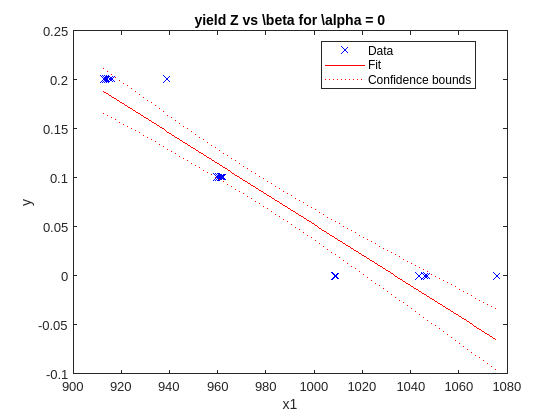


figure()
mdl = fitlm(yield_ZZ_for_f_alpha_0, f_beta_for_f_alpha_0);
plot(mdl);
title('yield Z vs \beta for \alpha = 0')

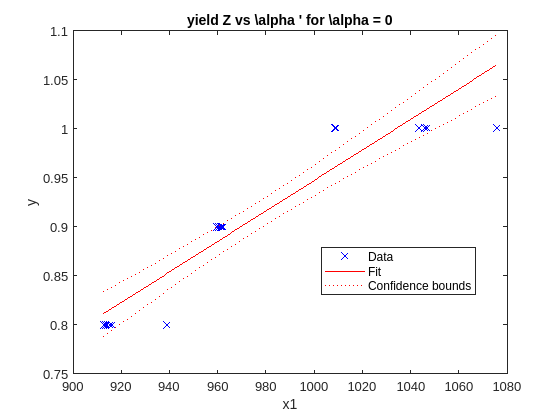

figure()
mdl = fitlm(yield_ZZ_for_f_alpha_0, f_mart_for_f_alpha_0);
plot(mdl);
title("yield Z vs \alpha ' for \alpha = 0")

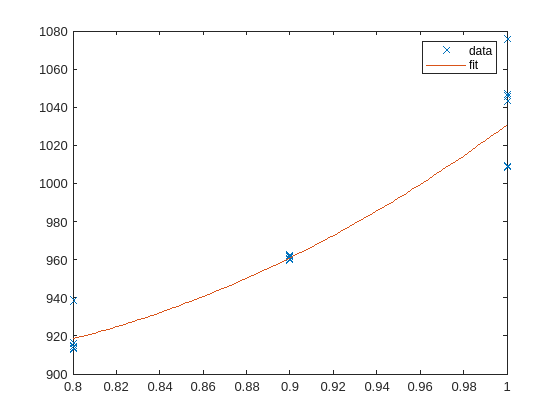


figure()
p = polyfit( f_mart_for_f_alpha_0,yield_ZZ_for_f_alpha_0,2);
x1 = linspace(0.8,1);
y1 = polyval(p,x1);
plot(f_mart_for_f_alpha_0,yield_ZZ_for_f_alpha_0,'X')
hold on
plot(x1,y1)
hold off
legend("data","fit")

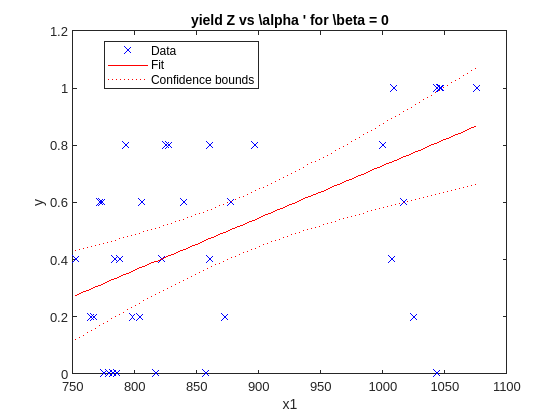




figure()
mdl = fitlm(yield_ZZ_for_f_beta_0, f_mart_for_f_beta_0);
plot(mdl);
title("yield Z vs \alpha ' for \beta = 0")

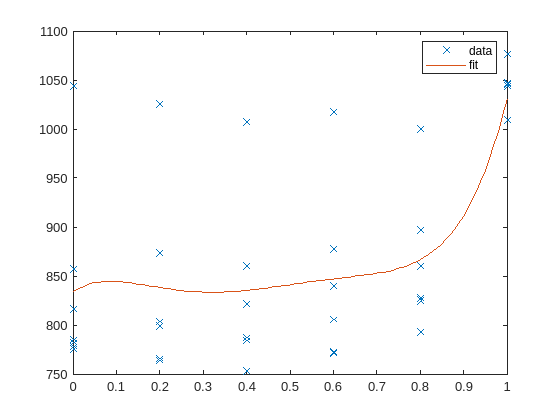


figure()
p = polyfit( f_mart_for_f_beta_0,yield_ZZ_for_f_beta_0,5);
x1 = linspace(0,1);
y1 = polyval(p,x1);
plot(f_mart_for_f_beta_0,yield_ZZ_for_f_beta_0,'X')
hold on
plot(x1,y1)
hold off
legend("data","fit")

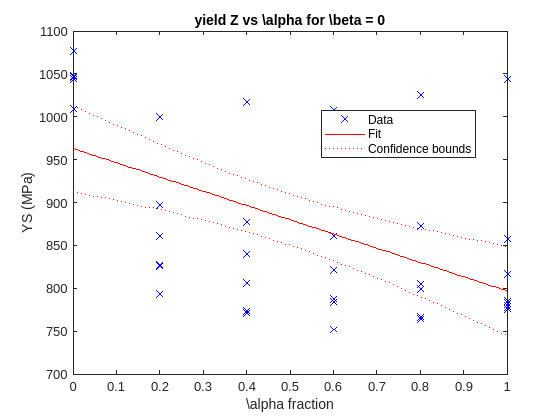

figure()
mdl = fitlm(f_alpha_for_f_beta_0,yield_ZZ_for_f_beta_0);
plot(mdl);
xlabel('\alpha fraction')
ylabel('YS (MPa)')
title('yield Z vs \alpha for \beta = 0')

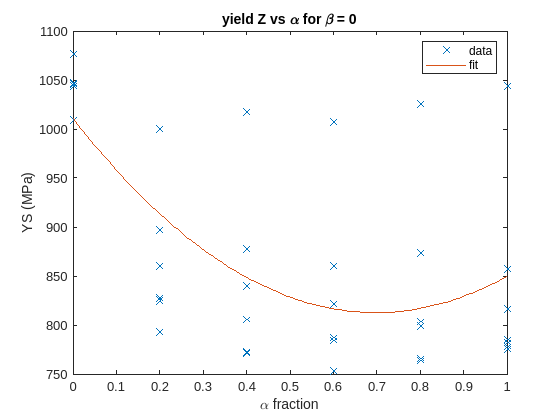


figure()
p = polyfit(f_alpha_for_f_beta_0,yield_ZZ_for_f_beta_0,2);
x1 = linspace(0,1);
y1 = polyval(p,x1);
plot(f_alpha_for_f_beta_0,yield_ZZ_for_f_beta_0,'X')
hold on
plot(x1,y1)
hold off
legend("data","fit")
xlabel('\alpha fraction')
ylabel('YS (MPa)')
title('yield Z vs \alpha for \beta = 0')



figure()
p = polyfit(f_beta_for_lath_0,yield_ZZ_for_lath_0,2);

Unrecognized function or variable 'f_beta_for_lath_0'.

x1 = linspace(0,1);
y1 = polyval(p,x1);
plot(f_beta_for_lath_0,yield_ZZ_for_lath_0,'X')
hold on
plot(x1,y1)
hold off
legend("data","fit")
xlabel('\alpha fraction')
ylabel('YS (MPa)')
title('yield Z vs \alpha for \beta = 0')

for i=1:1:25
    "TW"+num2str(i)
end
